# Teoría 8: Interpolación

## Polinomio interpolante

$f(x)=P_{n-1}(x)$     si y solo sí     $y=a_{n-1}x^{n-1}+\cdots+a_{1}x+a_0$

Hay $n$ incognitas (coeficientes)

- Se necesitan $n$ datos $(x_i,y_i)$: $(x_0,y_0),(x_1,y_1),\dots,(x_{n-1},y_{n-1})$

### Sistema Determinado

Evaluando se llega al **sistema** (lineal) **determinado** 

                                        
$$M a = y$$


% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]';

M = vander(xi)

M =        0              0              0              1       
      27              9              3              1       
      64             16              4              1       
     343             49              7              1       


format rational
a = M \ yi % coeficientes del polinomio

a =       -2/7     
      13/4     
    -229/28    
       5       


Veamos el polinomio

syms t
p_new = sum(a' .* [t^3 t^2 t 1])

$$p\_new = -\frac{2\,t^{3}}{7}+\frac{13\,t^{2}}{4}-\frac{229\,t}{28}+5$$

p_poly = polyfit(xi,yi,length(xi)-1) % coeficientes

p_poly =       -2/7           13/4         -229/28           5       


Obs: Una forma estándar de trabajar polinomios en MATLAB es almacenar los coeficientes de mayor a menor potencia (como vector fila)

### Polinomio interpolante de Newton

% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]';

% Tabla de diferencias divididas
M = tabladif(xi, yi);
disp(table(M(:,1),M(:,2),M(:,3),M(:,4),M(:,5),...
    'VariableNames',{'xi','yi','y[,]','y[,,]','y[,,,]'}))

    xi    yi    y[,]    y[,,]     y[,,,] 
    __    __    ____    _____    ________

    0     5      -1      1.25    -0.28571
    3     2       4     -0.75           0
    4     6       1         0           0
    7     9       0         0           0




$$P_{3}(x)=y[x_0]+y[x_0,x_1](x-x_0)+y[x_0,x_1,x_2](x-x_0)(x-x_1)+y[x_0,x_1,x_2,x_3](x-x_0)(x-x_1)(x-x_2)$$


% Polinomio de Newton
format rational
p_newton = polynewton(xi, yi)

p_newton =       -2/7           13/4         -229/28           5       


format short

Obs: Otra funcionalidad útil

p = poly(3)

p =      1    -3



$$p(x) = x-3$$


p = poly([3 2])

p =      1    -5     6



$$p(x)=x^2-5x+6$$



$$p(x)=(x-3)(x-2)$$


Y así en general

### Polinomio interpolante de Lagrange

% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]';

% Polinomios básicos
syms x_a x_b x_c x_d x
x_sym = [x_a; x_b; x_c; x_d]

$$x\_sym = \left(\begin{array}{c} x_{a}\\ x_{b}\\ x_{c}\\ x_{d} \end{array}\right)$$

p_basis = lagrange_basis(x_sym,x)

$$p\_basis = \left(\begin{array}{c} \frac{\left(x-x_{b}\right)\,\left(x-x_{c}\right)\,\left(x-x_{d}\right)}{\left(x_{a}-x_{b}\right)\,\left(x_{a}-x_{c}\right)\,\left(x_{a}-x_{d}\right)}\\ -\frac{\left(x-x_{a}\right)\,\left(x-x_{c}\right)\,\left(x-x_{d}\right)}{\left(x_{a}-x_{b}\right)\,\left(x_{b}-x_{c}\right)\,\left(x_{b}-x_{d}\right)}\\ \frac{\left(x-x_{a}\right)\,\left(x-x_{b}\right)\,\left(x-x_{d}\right)}{\left(x_{a}-x_{c}\right)\,\left(x_{b}-x_{c}\right)\,\left(x_{c}-x_{d}\right)}\\ -\frac{\left(x-x_{a}\right)\,\left(x-x_{b}\right)\,\left(x-x_{c}\right)}{\left(x_{a}-x_{d}\right)\,\left(x_{b}-x_{d}\right)\,\left(x_{c}-x_{d}\right)} \end{array}\right)$$

% Polinomio de Lagrange en simbólico
syms y_a y_b y_c y_d
y_sym = [y_a; y_b; y_c; y_d];
p_sym = sum(y_sym(:) .* p_basis(:))

$$p\_sym = \frac{y_{a}\,\left(x-x_{b}\right)\,\left(x-x_{c}\right)\,\left(x-x_{d}\right)}{\left(x_{a}-x_{b}\right)\,\left(x_{a}-x_{c}\right)\,\left(x_{a}-x_{d}\right)}-\frac{y_{b}\,\left(x-x_{a}\right)\,\left(x-x_{c}\right)\,\left(x-x_{d}\right)}{\left(x_{a}-x_{b}\right)\,\left(x_{b}-x_{c}\right)\,\left(x_{b}-x_{d}\right)}+\frac{y_{c}\,\left(x-x_{a}\right)\,\left(x-x_{b}\right)\,\left(x-x_{d}\right)}{\left(x_{a}-x_{c}\right)\,\left(x_{b}-x_{c}\right)\,\left(x_{c}-x_{d}\right)}-\frac{y_{d}\,\left(x-x_{a}\right)\,\left(x-x_{b}\right)\,\left(x-x_{c}\right)}{\left(x_{a}-x_{d}\right)\,\left(x_{b}-x_{d}\right)\,\left(x_{c}-x_{d}\right)}$$

% Polinomio de Lagrange con datos 
format rational
p_lagrange = lagrange(xi, yi)

p_lagrange =       -2/7           13/4         -229/28           5       


% Lagrange con los datos en simbólico
p_lagrange2 = subs(p_sym,[x_sym; y_sym], [xi; yi])

$$p\_lagrange2 = \frac{3\,x\,\left(x-3\right)\,\left(x-4\right)}{28}-\frac{x\,\left(x-3\right)\,\left(x-7\right)}{2}+\frac{x\,\left(x-4\right)\,\left(x-7\right)}{6}-\frac{5\,\left(x-3\right)\,\left(x-4\right)\,\left(x-7\right)}{84}$$

p_lagrange2 = simplify(p_lagrange2)

$$p\_lagrange2 = -\frac{2\,x^{3}}{7}+\frac{13\,x^{2}}{4}-\frac{229\,x}{28}+5$$

### Comparación gráfica

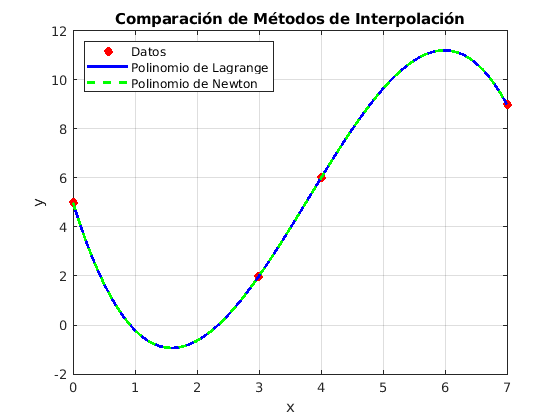

% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]';

% Polinomio de Newton
p_newton = polynewton(xi, yi);

% Polinomio de Lagrange
p_lagrange = lagrange(xi, yi);

% Para evaluar
xq = 0:0.1:7;

% Evaluar los polinomios en un conjunto de puntos
yq_lagrange = polyval(p_lagrange, xq);
yq_newton = polyval(p_newton, xq);

% Graficar los datos y los polinomios de interpolación
figure;
plot(xi, yi, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(xq, yq_lagrange, 'b-', 'LineWidth', 2);
plot(xq, yq_newton, 'g--', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Comparación de Métodos de Interpolación');
legend('Datos', 'Polinomio de Lagrange', 'Polinomio de Newton',"Location","northwest");
grid on;
hold off;

### Error de interpolación

Definición: error (función)

                            
$$E_n(x,f) = f(x) - P_n(x)$$


Estimación analítica (Taylor)

                            
$$E_n(x,f) = \frac{f^{(n+1)}(\xi(x))}{(n+1)!}(x-x_0)\ldots(x-x_n)$$


format short
% Datos de ejemplo
xi = [0 0.6 0.9]'

xi =          0
    0.6000
    0.9000


yi = cos(xi) % f(x) = cos(x)

yi =     1.0000
    0.8253
    0.6216


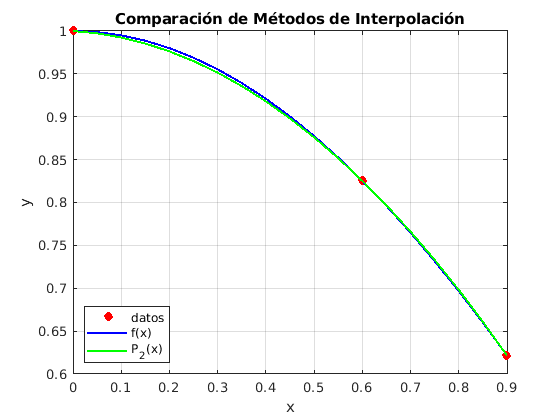

% Polinomio de Newton
p_newton = polynewton(xi, yi);

% Para evaluar
xq = 0:0.05:0.9;
yq_newton = polyval(p_newton, xq);
yq_exacto = cos(xq);

% Graficar los datos y los polinomios de interpolación
figure;
plot(xi, yi, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(xq, yq_exacto, 'b-', 'LineWidth', 1.5);
plot(xq, yq_newton, 'g-', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
title('Comparación de Métodos de Interpolación');
legend('datos', 'f(x)', 'P_2(x)',"Location","southwest");
grid on;
hold off;

Ejemplo: $f(x)=\cos(x)$ 

                            
$$E_2(x,f)=\frac{f^{3}(\xi(x))}{3!}x(x-0.6)(x-0.9)$$



$$f^3(x)=\sin(x)$$


$E_2(0.45,f)=$0.0023

format short

% Error absoluto en 0.45 (para un valor)
xq = 0.45;
yq_newton = polyval(p_newton, xq);  % polinomio
yq_exacto = cos(xq);                % modelo exacto
E = abs(yq_newton-yq_exacto)

E = 0.0023

% Cota del error absoluto en 0.45
syms t
f_xxx = matlabFunction(diff(cos(t),t,3))

f_xxx = function_handle with value:
    @(t)sin(t)


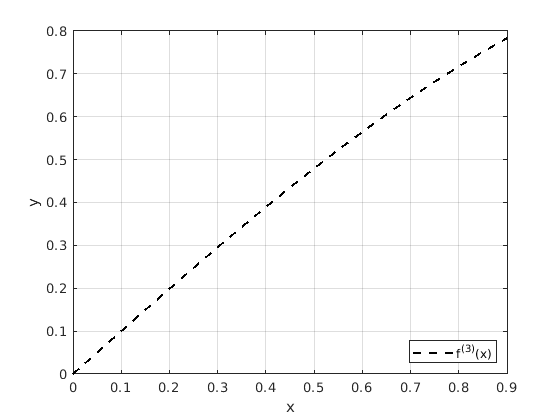

% Graficar la derivada de orden 3
xq = 0:0.05:0.9;
yq_derivada3 = sin(xq);
figure;
plot(xq, yq_derivada3, 'k--', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
legend('f^{(3)}(x)',"Location","southeast");
grid on;
hold off;

% Cota
xq = 0.45;
E_cota = abs( f_xxx(0.9) * (xq - xi(1)) * (xq - xi(2)) * (xq - xi(3)) ) / factorial(3)

E_cota = 0.0040

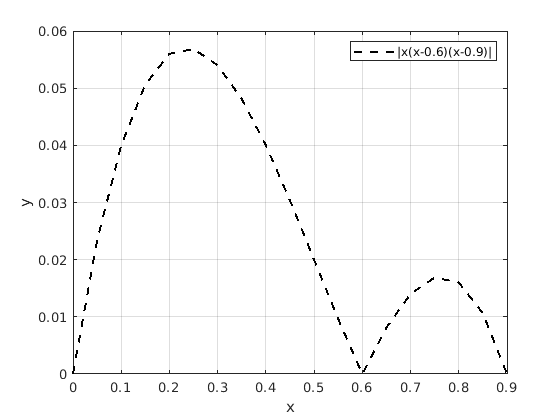

% Cota del error (cota de la función error)
% Graficar |(x-x0)(x-x1)(x-x2)|
g=@(x) (x-xi(1)) .* (x-xi(2)) .* (x-xi(3));
xq = 0:0.05:0.9;
yq_g = abs(g(xq));
figure;
plot(xq, yq_g, 'k--', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
%legend('|\Pi (x-x_i)|',"Location","northeast");
legend('|x(x-0.6)(x-0.9)|',"Location","northeast");
grid on;
hold off;

% Puntos críticos
syms t
g(t)

$$ans = t\,\left(t-\frac{3}{5}\right)\,\left(t-\frac{9}{10}\right)$$

x_crit = solve(diff(g(t),t) == 0);
double(x_crit)

ans =     0.2354
    0.7646


abs(g(double(x_crit)))

ans =     0.0570
    0.0170


x_max = double(x_crit(1));

% Cota
E_cota = abs( f_xxx(0.9) * g(x_max) ) / factorial(3)

E_cota = 0.0074

Estimación numérica (solo con datos)

Regla del término siguiente: para $y=f(x)$

                                
$$E_n(x,f) \approx y[x_0,\ldots,x_n,x_{n+1}](x-x_0)\ldots(x-x_n)$$


Nota que el polinomio interpolante es $P_n(x)=y[x_0]+\cdots y[x_0,\ldots,x_n](x-x_0)\ldots(x-x_{n-1})$

% Datos de ejemplo
xi = [0 0.6 0.9]';
yi = cos(xi);

% Tabla de diferencias divididas
M = tabladif(xi, yi)

M =          0    1.0000   -0.2911   -0.4311
    0.6000    0.8253   -0.6791         0
    0.9000    0.6216         0         0


% Regla del término siguiente
xq = 0.45;
P1 = polyfit(xi(1:end-1),yi(1:end-1),1); % Polinomio de grado 1
yq = polyval(P1,xq) % P1(0.45)

yq = 0.8690

% Diferencia dividida de mayor orden posible (2)
M(1,end)

ans = -0.4311

% Estimación del error
E = M(1,end)*prod(xq-xi(1:end-1))

E = 0.0291

% Otra forma de calcular
P2 = polyfit(xi,yi,2); % Polinomio de grado 2
E = polyval(P2,xq) - polyval(P1,xq)

E = 0.0291

## Spline cúbico natural

Para los datos 

                
$$(x_0,y_0),(x_1,y_1),(x_2,y_2)$$


Ahora el modelo $f(x)$ es un conjunto de polinomios cúbico 

            
$$\left\{ 
\begin{array}{cc}
S_0(x)=a_0x^3+b_0x^2+c_0 x+d_0 & x_0 \le x \le x_1 \\
S_1(x)=a_1x^3+b_1x^2+c_1 x+d_1 & x_1 \le x \le x_2 
\end{array}
\right.$$


### Algoritmo

    
$$\left\{ 
\begin{array}{cc}
S_0(x)=a_0(x-x_0)^3+b_0(x-x_0)^2+c_0 (x-x_0)+d_0 & x_0 \le x \le x_1 \\
S_1(x)=a_1(x-x_1)^3+b_1(x-x_1)^2+c_1 (x-x_1)+d_1 & x_1 \le x \le x_2 
\end{array}
\right.$$


% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]'; 

% Spline Cúbico Natural
S = splinenatural(xi, yi)

S =     0.2275         0   -3.0476    5.0000
   -1.1429    2.0476    3.0952    2.0000
    0.1534   -1.3810    3.7619    6.0000


### Comparación gráfica

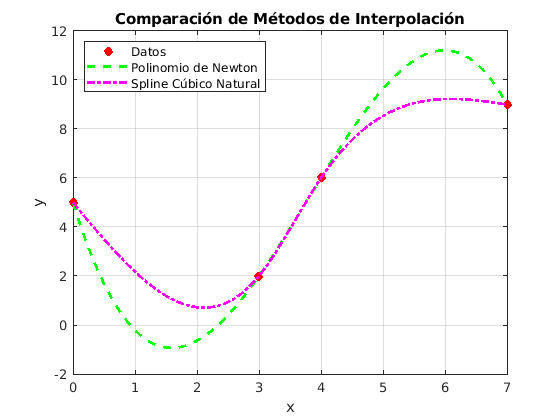

% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]'; 

% Spline Cúbico Natural
S = splinenatural(xi, yi);

% Para evaluar
xq = [0:0.1:7]';
[~,yq_spline] = splinenatural(xi, yi,xq); % apartar como método la evaluación

% Evaluar los polinomios en un conjunto de puntos
p_newton = polynewton(xi, yi);
yq_newton = polyval(p_newton, xq);

% Graficar los datos y los polinomios de interpolación
figure;
plot(xi, yi, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(xq, yq_newton, 'g--', 'LineWidth', 2);
plot(xq, yq_spline, 'm-.', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Comparación de Métodos de Interpolación');
legend('Datos','Polinomio de Newton', 'Spline Cúbico Natural',...
    "Location","northwest");
grid on;
hold off;

function p = lagrange_basis(x_val,x_sym)
    %   p = LAGRANGE_BASIS(x) devuelve los polinomios básicos de Lagrange
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       x_sym - Variable simbólica de la variable independiente.
    %
    %   Salida:
    %       p - Vector simbólico con los polinomios básicos de Lagrange.

    n = length(x_val);      % Número de puntos

    % Construir el polinomio de Lagrange
    p = [];
    for k=1:n
        x_menos = x_val([1:k-1, k+1:n]);
        p = [p; prod(x_sym-x_menos)/prod(x_val(k)-x_menos)];
    end
end

function p = lagrange(x, y)
    %   p = LAGRANGE(x, y) devuelve los coeficientes del polinomio de interpolación
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       p - Vector de coeficientes del polinomio de interpolación de Lagrange.

    n = length(x);      % Número de puntos
    p = zeros(1, n);    % Inicializar el polinomio resultante

    % Construir el polinomio de Lagrange
    for k = 1:n
        num = poly(x([1:k-1, k+1:n])); % Numerador del término de Lagrange
        den = polyval(num, x(k));      % Denominador del término de Lagrange
        L = num / den;                 % Término de Lagrange
        p = p + y(k) * L;              % Sumar el término de Lagrange al polinomio
    end
end

function M = tabladif(x, y)
    %   M = TABLADIF(x, y) devuelve la tabla de diferencias divididas de Newton
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       M - Matriz donde la primera columna es x y las siguientes columnas
    %           contienen las diferencias divididas.

    n = length(x);      % Número de puntos
    M = zeros(n);       % Inicializar la matriz M
    M(1:n, 1) = y;      % Primera columna de M es y

    % Calcular las diferencias divididas
    for k = 1:n-1
        dx = x(k+1:n) - x(1:n-k); % Diferencias de x
        dy = diff(y) ./ dx;       % Diferencias divididas
        M(1:n-k, k+1) = dy;       % Llenar la columna k+1 de M
        y = dy;                   % Actualizar y para el siguiente paso
    end

    M = [x(:) M]; % Añadir la columna x al principio de la matriz M
end

function p = polynewton(x, y)
    %   p = POLYNEWTON(x, y) devuelve los coeficientes del polinomio de interpolación
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       p - Vector de coeficientes del polinomio de interpolación de Newton.

    M = tabladif(x, y); % Obtener la tabla de diferencias divididas
    n = length(x);      % Número de puntos
    b = M(1, 2:end);    % Coeficientes del polinomio de Newton
    p = b(1);           % Inicializar el polinomio con el primer coeficiente

    % Construir el polinomio de Newton
    for k = 2:n
        % Actualizar el polinomio con el siguiente término
        p = [0 p] + b(k) * poly(x(1:k-1)); 
    end
end

function [S, yq] = splinenatural(X, Y, xq, draw)
    % SPLINENATURAL Interpolación usando splines cúbicos naturales.
    %   [S, yq] = splinenatural(X, Y, xq, draw) devuelve los coeficientes de los
    %   polinomios cúbicos y los valores interpolados en los puntos de consulta.
    %
    %   Entrada:
    %       X    - Vector fila de puntos de datos.
    %       Y    - Vector fila de valores de la función en los puntos X.
    %       xq   - Vector fila de puntos a evaluar en la interpolación.
    %       draw - Lógico (0 o 1), indica si se grafica la interpolación (opcional).
    %
    %   Salida:
    %       S  - Matriz de coeficientes de los polinomios cúbicos (cada fila es un polinomio).
    %       yq - Vector fila de valores interpolados en los puntos xq.

    if nargin < 4
        draw = 0; % Por defecto no se grafica
        if nargin < 3
            xq = NaN; % Si no se proporcionan puntos de consulta, se establece como NaN
        end
    end
    
    X = X(:); % Convertir X como arreglo fila
    Y = Y(:); % Convertir Y como arreglo fila
    N = length(X) - 1; % Número de intervalos
    H = diff(X); % Diferencias entre puntos X
    E = diff(Y) ./ H; % Pendientes de los intervalos

    % Matriz de coeficientes de las segundas derivadas
    diagprinc = 2 * (H(1:N-1) + H(2:N)); 
    diagsupinf = H(2:N-1);
    A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1);

    % Vector de términos independientes
    b = 6 * diff(E);

    % Resolver el sistema lineal para encontrar las segundas derivadas
    g = A \ b; 
    g = [0; g; 0]; % Añadir condiciones de frontera naturales

    % Inicializar la salida yq
    yq = NaN(size(xq));
    S = zeros(N, 4); % Inicializar matriz de coeficientes

    % Calcular los coeficientes de los polinomios cúbicos
    for i = 1:N
        S(i, 1) = (g(i+1) - g(i)) / (6 * H(i));
        S(i, 2) = g(i) / 2;
        S(i, 3) = E(i) - H(i) * (g(i+1) + 2 * g(i)) / 6;
        S(i, 4) = Y(i);

        % Evaluar los polinomios en los puntos de consulta
        indx = find(xq >= X(i) & xq <= X(i+1)); 
        yq(indx) = S(i, 1) * (xq(indx) - X(i)).^3 + S(i, 2) * (xq(indx) - X(i)).^2 + S(i, 3) * (xq(indx) - X(i)) + S(i, 4);

        % Graficar si se solicita
        if draw == 1
            xx = linspace(X(i), X(i+1), 100);
            yy = S(i, 1) * (xx - X(i)).^3 + S(i, 2) * (xx - X(i)).^2 + S(i, 3) * (xx - X(i)) + S(i, 4);
            plot(xx, yy) 
            hold on
        end
    end

    % Configuración de la gráfica
    if draw == 1
        grid on 
        hold off
    end
end